# create downsampled vector of all aluminum times without the artifact times

params = '/home/ben/Z/Parameters_files/FVB/FVB103_270721_757.m';
run(params)

experiment = auditory_ephys_exp(params);

Choose csv file for the whisking camera
Choose csv file for the face camera


data = load_open_ephys_binary([exp_path,'/experiment1/recording1/structure.oebin'],'continuous',1,'mmap');
aud_data = data.Data.Data.mapped(32 + mic,:)

aud_data = 1×63532032 int16 row vector
   345   344   359   379   294   335   322   319   377   321   331   367   412   366   311   372   259   250   313   349   326   331   352   323   347   348   319   375   371   353   327   334   378   369   384   350   323   335   373   367   379   313   305   315   327   281   302   295   351   366


% find time samples in video based on whiskers for both whiskers and face
whiskingStart = experiment.Cams.whsiking.csv_start_frame

whiskingStart = 398

expLength = length(data.Data.Data.mapped)

expLength = 63532032

whiskingEnd = find(experiment.Cams.whsiking.csv_aligned_frames < expLength);
whiskingEnd = whiskingEnd(end)

whiskingEnd = 845864

whiskingVector = [whiskingStart:whiskingEnd]

whiskingVector =    398   399   400   401   402   403   404   405   406   407   408   409   410   411   412   413   414   415   416   417   418   419   420   421   422   423   424   425   426   427   428   429   430   431   432   433   434   435   436   437   438   439   440   441   442   443   444   445   446   447


sampleVector = experiment.Cams.whsiking.csv_aligned_frames(whiskingVector)

sampleVector =        76769
       76947
       77020
       77094
       77164
       77237
       77323
       77391
       77473
       77546



[~,faceStart] = min(abs(experiment.Cams.face.csv_aligned_frames - sampleVector(1)))

faceStart = 413

faceVector = [faceStart:faceStart+length(whiskingVector)-1]

faceVector =    413   414   415   416   417   418   419   420   421   422   423   424   425   426   427   428   429   430   431   432   433   434   435   436   437   438   439   440   441   442   443   444   445   446   447   448   449   450   451   452   453   454   455   456   457   458   459   460   461   462


% Extract aluminum times
artifactStart = experiment.Conditions.artifact_times(2) * 30

artifactStart = 75000

artifactEnd = experiment.Conditions.artifact_times(1) * 30

artifactEnd = 90000

all_times = [experiment.Conditions.all_changes + artifactStart,[experiment.Conditions.all_changes(2:end);sampleVector(end)]-artifactEnd]

all_times = 33×2 int64 matrix
    4786818    6511339
    6676339    8400861
    8565861   10290384
   10455384   12173912
   12338912   14051438
   14216438   15928965
   16093965   17818491
   17983491   19696063
   19861063   21573592
   21738592   23463119


aluminumTimes = all_times(experiment.Conditions.condition_classification == 1,:)

aluminumTimes = 8×2 int64 matrix
    4786818    6511339
   14216438   15928965
   16093965   17818491
   19861063   21573592
   21738592   23463119
   25505648   27224177
   59676650   61389170
   61554170   63278688


% create idx vector for aluminum
aluminumInd = []


aluminumInd =

     []



for al = 1:length(aluminumTimes)
    tempInd = find(sampleVector > aluminumTimes(al,1) & sampleVector < aluminumTimes(al,2))
    aluminumInd = [aluminumInd;tempInd]
end

tempInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


tempInd =       188400
      188401
      188402
      188403
      188404
      188405
      188406
      188407
      188408
      188409


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


tempInd =       213413
      213414
      213415
      213416
      213417
      213418
      213419
      213420
      213421
      213422


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


tempInd =       263610
      263611
      263612
      263613
      263614
      263615
      263616
      263617
      263618
      263619


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


tempInd =       288623
      288624
      288625
      288626
      288627
      288628
      288629
      288630
      288631
      288632


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


tempInd =       338819
      338820
      338821
      338822
      338823
      338824
      338825
      338826
      338827
      338828


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


tempInd =       794101
      794102
      794103
      794104
      794105
      794106
      794107
      794108
      794109
      794110


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


tempInd =       819115
      819116
      819117
      819118
      819119
      819120
      819121
      819122
      819123
      819124


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


% create samplevector for aluminum
aluminumVector = sampleVector(aluminumInd)

aluminumVector =      4786826
     4786903
     4786975
     4787053
     4787131
     4787212
     4787278
     4787360
     4787435
     4787504


% create video frame whisker vector
aluminumWhiskerVector = whiskingVector(aluminumInd)'

aluminumWhiskerVector =        63155
       63156
       63157
       63158
       63159
       63160
       63161
       63162
       63163
       63164


% create video frame face vector
aluminumFaceVector = faceVector(aluminumInd)'

aluminumFaceVector =        63170
       63171
       63172
       63173
       63174
       63175
       63176
       63177
       63178
       63179


## **create matrix for prediction with linear regression**

### **The model is a matrix with the following rows as variables and columuns as observations:**

- ** Encoder**

- **whiskingMotion_1**

- **whisking motSVD_0 (10 first)**

- **whisking motSVD_1 (10 first)**

- **faceMotion_1**

- **face motSVD_1 (10 first)**

- **Running from face camera**

**Predictions should be done on a matrix ordered the same why**

**The output will be a vector of the sound from open ephys sampled by the sampleVector and threshold **

% get the sound vector 
%aud_data = data.Data.Data.mapped(34,:)

[b,a] = butter(3,[10]/15000,'high')

b =     0.9979   -2.9937    2.9937   -0.9979


a =     1.0000   -2.9958    2.9916   -0.9958


aud_data = filtfilt(b,a,double(aud_data))

aud_data = 	1.0e+03 *

   -0.0038   -0.0048    0.0103    0.0303   -0.0547   -0.0136   -0.0266   -0.0296    0.0284   -0.0275   -0.0175    0.0185    0.0636    0.0176   -0.0374    0.0237   -0.0893   -0.0983   -0.0353    0.0008   -0.0222   -0.0172    0.0039   -0.0251   -0.0011   -0.0001   -0.0290    0.0270    0.0230    0.0051   -0.0209   -0.0139    0.0302    0.0212    0.0362    0.0022   -0.0247   -0.0127    0.0253    0.0194    0.0314   -0.0346   -0.0426   -0.0325   -0.0205   -0.0665   -0.0454   -0.0524    0.0036    0.0187


% get the aluminum sound vector 
%aud_data = aud_data(aluminumVector)

% clean artifacts clipping
aud_data(aud_data > 1000 | aud_data < -1000) = 0;

% clean data below threshold
aud_data = abs(aud_data)

aud_data =     3.7865    4.7572   10.2721   30.3015   54.6692   13.6399   26.6105   29.5812   28.4482   27.5225   17.4931   18.5362   63.5656   17.5949   37.3757   23.6536   89.3170   98.2877   35.2583    0.7710   22.1996   17.1703    3.8591   25.1115    1.0822    0.0528   29.0235   27.0059   23.0353    5.0646   20.9060   13.8766   30.1527   21.1821   36.2115    2.2408   24.7298   12.7004   25.3289   19.3583   31.3877   34.5830   42.5536   32.5242   20.4949   66.4655   45.4362   52.4068    3.6226   18.6519


aud_data = normalize(aud_data,'range')

aud_data =     0.0038    0.0048    0.0103    0.0303    0.0547    0.0136    0.0266    0.0296    0.0284    0.0275    0.0175    0.0185    0.0636    0.0176    0.0374    0.0237    0.0893    0.0983    0.0353    0.0008    0.0222    0.0172    0.0039    0.0251    0.0011    0.0001    0.0290    0.0270    0.0230    0.0051    0.0209    0.0139    0.0302    0.0212    0.0362    0.0022    0.0247    0.0127    0.0253    0.0194    0.0314    0.0346    0.0426    0.0325    0.0205    0.0665    0.0454    0.0524    0.0036    0.0187


experiment.sound_events.fullSound = aud_data;

aud_data_cleaned = aud_data(aluminumVector)

aud_data_cleaned =     0.0133    0.0908    0.0522    0.0062    0.0101    0.0369    0.0210    0.0610    0.0009    0.0111    0.0311    0.0052    0.0053    0.0303    0.0374    0.0406    0.0215    0.0045    0.0195    0.0244    0.0544    0.0004    0.0204    0.0525    0.0235    0.0435    0.0646    0.0287    0.0167    0.0028    0.0041    0.0309    0.0452    0.0207    0.0206    0.0225    0.0087    0.0498    0.0711    0.0400    0.0540    0.0079    0.0462    0.0842    0.0263    0.0057    0.0343    0.0323    0.0223    0.0447


%aud_data_cleaned(aud_data_cleaned < 0.1) = 0

figure; plot(aud_data_cleaned)

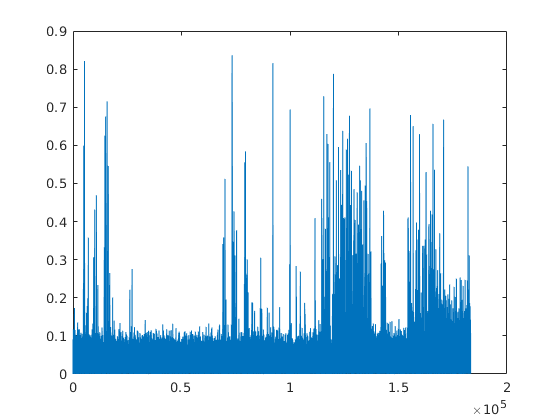

% get encoder data and high pass filter 
encoder_data = data.Data.Data.mapped(32 + encoder,:)

[b,a] = butter(3,[2]/30000,'high')
encoder_data = filtfilt(b,a,double(encoder_data))

% add encoder to the modal and prediction matrices

encoder_data = 1×53851648 int16 row vector
   5493   5499   5503   5494   5491   5491   5499   5499   5503   5491   5490   5498   5497   5486   5503   5497   5503   5487   5491   5495   5498   5501   5499   5497   5503   5501   5495   5499   5505   5497   5493   5505   5504   5504   5495   5498   5493   5502   5499   5489   5502   5497   5501   5496   5494   5499   5501   5494   5496   5499


modelMatrix = encoder_data(aluminumVector)

b =     0.9998   -2.9994    2.9994   -0.9998


a =     1.0000   -2.9996    2.9992   -0.9996


predictionMatrix = encoder_data(sampleVector)

encoder_data = 	1.0e+04 *

   -0.0004    0.0002    0.0006   -0.0003   -0.0006   -0.0006    0.0002    0.0002    0.0006   -0.0006   -0.0007    0.0001    0.0000   -0.0011    0.0006    0.0000    0.0006   -0.0010   -0.0006   -0.0002    0.0001    0.0004    0.0002    0.0000    0.0006    0.0004   -0.0002    0.0002    0.0008    0.0000   -0.0004    0.0008    0.0007    0.0007   -0.0002    0.0001   -0.0004    0.0005    0.0002   -0.0008    0.0005    0.0000    0.0004   -0.0001   -0.0003    0.0002    0.0004   -0.0003   -0.0001    0.0002


% import the whisking moiton vectors
[file,path] = uigetfile();

modelMatrix = 	1.0e+04 *

   -0.1276   -0.1223   -0.1159   -0.1113   -0.1059   -0.1000   -0.0962   -0.0914   -0.0862   -0.0824   -0.0734   -0.0705   -0.0656   -0.0625   -0.0563   -0.0512   -0.0477   -0.0436   -0.0375   -0.0349   -0.0296   -0.0239   -0.0217   -0.0170   -0.0129   -0.0092   -0.0052   -0.0008    0.0014    0.0049    0.0078    0.0133    0.0156    0.0202    0.0227    0.0253    0.0279    0.0303    0.0351    0.0378    0.0409    0.0423    0.0461    0.0470    0.0505    0.0503    0.0537    0.0557    0.0578    0.0585


cd(path)

predictionMatrix = 	1.0e+04 *

    0.0003   -0.0007   -0.0003   -0.0007    0.0005    0.0013    0.0002    0.0005    0.0009   -0.0006   -0.0005    0.0009    0.0005    0.0003   -0.0004   -0.0019    0.0001    0.0010    0.0011   -0.0013   -0.0003   -0.0006   -0.0000    0.0005   -0.0009    0.0006   -0.0002   -0.0004    0.0001    0.0005    0.0013   -0.0007    0.0012    0.0004    0.0004    0.0004    0.0000   -0.0006    0.0000   -0.0008   -0.0008    0.0000   -0.0014   -0.0004    0.0003   -0.0004    0.0000   -0.0004   -0.0005    0.0000


load(file,'motSVD_1','motion_1','motSVD_0')
try
    load(file,'motSVD_2')
catch 
    'no motSVD_2'
end

if ~isempty(motSVD_0)% add motion and motSVDs to the modal and prediciton matrices
    modelMatrix(2,:) = motion_1(aluminumWhiskerVector)
    predictionMatrix(2,:) = motion_1(whiskingVector)
    modelMatrix(3:12,:) = motSVD_0(aluminumWhiskerVector,1:10)'
    predictionMatrix(3:12,:) = motSVD_0(whiskingVector,1:10)'
    modelMatrix(13:22,:) = motSVD_1(aluminumWhiskerVector,1:10)'
    predictionMatrix(13:22,:) = motSVD_1(whiskingVector,1:10)'
    ind = 23
elseif exist('motSVD_2')
    modelMatrix(2,:) = motion_1(aluminumWhiskerVector)
    predictionMatrix(2,:) = motion_1(whiskingVector)
    modelMatrix(3:12,:) = motSVD_1(aluminumWhiskerVector,1:10)'
    predictionMatrix(3:12,:) = motSVD_1(whiskingVector,1:10)'
    modelMatrix(13:22,:) = motSVD_2(aluminumWhiskerVector,1:10)'
    predictionMatrix(13:22,:) = motSVD_2(whiskingVector,1:10)'
    ind = 23
else
    modelMatrix(2,:) = motion_1(aluminumWhiskerVector)
    predictionMatrix(2,:) = motion_1(whiskingVector)
    modelMatrix(3:12,:) = motSVD_1(aluminumWhiskerVector,1:10)'
    predictionMatrix(3:12,:) = motSVD_1(whiskingVector,1:10)'
    ind = 13
end


modelMatrix = 	1.0e+05 *

   -0.0128   -0.0122   -0.0116   -0.0111   -0.0106   -0.0100   -0.0096   -0.0091   -0.0086   -0.0082   -0.0073   -0.0070   -0.0066   -0.0062   -0.0056   -0.0051   -0.0048   -0.0044   -0.0038   -0.0035   -0.0030   -0.0024   -0.0022   -0.0017   -0.0013   -0.0009   -0.0005   -0.0001    0.0001    0.0005    0.0008    0.0013    0.0016    0.0020    0.0023    0.0025    0.0028    0.0030    0.0035    0.0038    0.0041    0.0042    0.0046    0.0047    0.0051    0.0050    0.0054    0.0056    0.0058    0.0058
    0.7728    0.8099    0.8792    0.8802    0.8764    0.8335    0.7195    0.5331    0.4316    0.3974    0.3824    0.3592    0.3856    0.4339    0.4512    0.4301    0.4657    0.4683    0.4368    0.4050    0.3929    0.3835    0.3873    0.4080    0.4126    0.4141    0.4214    0.4127    0.3975    0.3765    0.3836    0.3718    0.4103    0.4159    0.4166    0.4310    0.4133    0.4094    0.4021    0.4039    0.4496    0.4513    0.4352    0.4475    0.4218    0.4157    0.3900   

predictionMatrix = 	1.0e+05 *

    0.0000   -0.0001   -0.0000   -0.0001    0.0000    0.0001    0.0000    0.0000    0.0001   -0.0001   -0.0001    0.0001    0.0000    0.0000   -0.0000   -0.0002    0.0000    0.0001    0.0001   -0.0001   -0.0000   -0.0001   -0.0000    0.0000   -0.0001    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0001    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0001   -0.0001    0.0000   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1427    0.1630    0.1763    0.3011    0.1893    0.2040    0.1783    0.1402    0.1381    0.1680    0.2200    0.1932    0.1715    0.1726    0.1664    0.1923    0.1844    0.1514    0.1814    0.1697    0.1693    0.1864    0.1775    0.1855    0.1917    0.1889    0.1942    0.1912    0.1719    0.1848    0.1732    0.2170    0.1997    0.2137    0.1804    0.1674    0.1899    0.1762    0.1936    0.1947    0.1942    0.1786    0.1890    0.1666    0.1876    0.1862    0.20

modelMatrix = 	1.0e+05 *

   -0.0128   -0.0122   -0.0116   -0.0111   -0.0106   -0.0100   -0.0096   -0.0091   -0.0086   -0.0082   -0.0073   -0.0070   -0.0066   -0.0062   -0.0056   -0.0051   -0.0048   -0.0044   -0.0038   -0.0035   -0.0030   -0.0024   -0.0022   -0.0017   -0.0013   -0.0009   -0.0005   -0.0001    0.0001    0.0005    0.0008    0.0013    0.0016    0.0020    0.0023    0.0025    0.0028    0.0030    0.0035    0.0038    0.0041    0.0042    0.0046    0.0047    0.0051    0.0050    0.0054    0.0056    0.0058    0.0058
    0.7728    0.8099    0.8792    0.8802    0.8764    0.8335    0.7195    0.5331    0.4316    0.3974    0.3824    0.3592    0.3856    0.4339    0.4512    0.4301    0.4657    0.4683    0.4368    0.4050    0.3929    0.3835    0.3873    0.4080    0.4126    0.4141    0.4214    0.4127    0.3975    0.3765    0.3836    0.3718    0.4103    0.4159    0.4166    0.4310    0.4133    0.4094    0.4021    0.4039    0.4496    0.4513    0.4352    0.4475    0.4218    0.4157    0.3900   

predictionMatrix = 	1.0e+05 *

    0.0000   -0.0001   -0.0000   -0.0001    0.0000    0.0001    0.0000    0.0000    0.0001   -0.0001   -0.0001    0.0001    0.0000    0.0000   -0.0000   -0.0002    0.0000    0.0001    0.0001   -0.0001   -0.0000   -0.0001   -0.0000    0.0000   -0.0001    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0001    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0001   -0.0001    0.0000   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1427    0.1630    0.1763    0.3011    0.1893    0.2040    0.1783    0.1402    0.1381    0.1680    0.2200    0.1932    0.1715    0.1726    0.1664    0.1923    0.1844    0.1514    0.1814    0.1697    0.1693    0.1864    0.1775    0.1855    0.1917    0.1889    0.1942    0.1912    0.1719    0.1848    0.1732    0.2170    0.1997    0.2137    0.1804    0.1674    0.1899    0.1762    0.1936    0.1947    0.1942    0.1786    0.1890    0.1666    0.1876    0.1862    0.20

modelMatrix = 	1.0e+05 *

   -0.0128   -0.0122   -0.0116   -0.0111   -0.0106   -0.0100   -0.0096   -0.0091   -0.0086   -0.0082   -0.0073   -0.0070   -0.0066   -0.0062   -0.0056   -0.0051   -0.0048   -0.0044   -0.0038   -0.0035   -0.0030   -0.0024   -0.0022   -0.0017   -0.0013   -0.0009   -0.0005   -0.0001    0.0001    0.0005    0.0008    0.0013    0.0016    0.0020    0.0023    0.0025    0.0028    0.0030    0.0035    0.0038    0.0041    0.0042    0.0046    0.0047    0.0051    0.0050    0.0054    0.0056    0.0058    0.0058
    0.7728    0.8099    0.8792    0.8802    0.8764    0.8335    0.7195    0.5331    0.4316    0.3974    0.3824    0.3592    0.3856    0.4339    0.4512    0.4301    0.4657    0.4683    0.4368    0.4050    0.3929    0.3835    0.3873    0.4080    0.4126    0.4141    0.4214    0.4127    0.3975    0.3765    0.3836    0.3718    0.4103    0.4159    0.4166    0.4310    0.4133    0.4094    0.4021    0.4039    0.4496    0.4513    0.4352    0.4475    0.4218    0.4157    0.3900   

predictionMatrix = 	1.0e+05 *

    0.0000   -0.0001   -0.0000   -0.0001    0.0000    0.0001    0.0000    0.0000    0.0001   -0.0001   -0.0001    0.0001    0.0000    0.0000   -0.0000   -0.0002    0.0000    0.0001    0.0001   -0.0001   -0.0000   -0.0001   -0.0000    0.0000   -0.0001    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0001    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0001   -0.0001    0.0000   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1427    0.1630    0.1763    0.3011    0.1893    0.2040    0.1783    0.1402    0.1381    0.1680    0.2200    0.1932    0.1715    0.1726    0.1664    0.1923    0.1844    0.1514    0.1814    0.1697    0.1693    0.1864    0.1775    0.1855    0.1917    0.1889    0.1942    0.1912    0.1719    0.1848    0.1732    0.2170    0.1997    0.2137    0.1804    0.1674    0.1899    0.1762    0.1936    0.1947    0.1942    0.1786    0.1890    0.1666    0.1876    0.1862    0.20

ind = 23

% import data from face video
clear motion_1 motion_0 motSVD_1 motSVD_0
[file,path] = uigetfile();
cd(path)
load(file, 'motSVD_1','motion_1','running_0')

% add motion and motSVDs to the modal and prediciton matrices
modelMatrix(ind,:) = motion_1(aluminumFaceVector)

modelMatrix = 	1.0e+05 *

   -0.0128   -0.0122   -0.0116   -0.0111   -0.0106   -0.0100   -0.0096   -0.0091   -0.0086   -0.0082   -0.0073   -0.0070   -0.0066   -0.0062   -0.0056   -0.0051   -0.0048   -0.0044   -0.0038   -0.0035   -0.0030   -0.0024   -0.0022   -0.0017   -0.0013   -0.0009   -0.0005   -0.0001    0.0001    0.0005    0.0008    0.0013    0.0016    0.0020    0.0023    0.0025    0.0028    0.0030    0.0035    0.0038    0.0041    0.0042    0.0046    0.0047    0.0051    0.0050    0.0054    0.0056    0.0058    0.0058
    0.7728    0.8099    0.8792    0.8802    0.8764    0.8335    0.7195    0.5331    0.4316    0.3974    0.3824    0.3592    0.3856    0.4339    0.4512    0.4301    0.4657    0.4683    0.4368    0.4050    0.3929    0.3835    0.3873    0.4080    0.4126    0.4141    0.4214    0.4127    0.3975    0.3765    0.3836    0.3718    0.4103    0.4159    0.4166    0.4310    0.4133    0.4094    0.4021    0.4039    0.4496    0.4513    0.4352    0.4475    0.4218    0.4157    0.3900   

predictionMatrix(ind,:) = motion_1(faceVector)

predictionMatrix = 	1.0e+05 *

    0.0000   -0.0001   -0.0000   -0.0001    0.0000    0.0001    0.0000    0.0000    0.0001   -0.0001   -0.0001    0.0001    0.0000    0.0000   -0.0000   -0.0002    0.0000    0.0001    0.0001   -0.0001   -0.0000   -0.0001   -0.0000    0.0000   -0.0001    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0001    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0001   -0.0001    0.0000   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1427    0.1630    0.1763    0.3011    0.1893    0.2040    0.1783    0.1402    0.1381    0.1680    0.2200    0.1932    0.1715    0.1726    0.1664    0.1923    0.1844    0.1514    0.1814    0.1697    0.1693    0.1864    0.1775    0.1855    0.1917    0.1889    0.1942    0.1912    0.1719    0.1848    0.1732    0.2170    0.1997    0.2137    0.1804    0.1674    0.1899    0.1762    0.1936    0.1947    0.1942    0.1786    0.1890    0.1666    0.1876    0.1862    0.20

modelMatrix(ind+1:ind+10,:) = motSVD_1(aluminumFaceVector,1:10)'

modelMatrix = 	1.0e+05 *

   -0.0128   -0.0122   -0.0116   -0.0111   -0.0106   -0.0100   -0.0096   -0.0091   -0.0086   -0.0082   -0.0073   -0.0070   -0.0066   -0.0062   -0.0056   -0.0051   -0.0048   -0.0044   -0.0038   -0.0035   -0.0030   -0.0024   -0.0022   -0.0017   -0.0013   -0.0009   -0.0005   -0.0001    0.0001    0.0005    0.0008    0.0013    0.0016    0.0020    0.0023    0.0025    0.0028    0.0030    0.0035    0.0038    0.0041    0.0042    0.0046    0.0047    0.0051    0.0050    0.0054    0.0056    0.0058    0.0058
    0.7728    0.8099    0.8792    0.8802    0.8764    0.8335    0.7195    0.5331    0.4316    0.3974    0.3824    0.3592    0.3856    0.4339    0.4512    0.4301    0.4657    0.4683    0.4368    0.4050    0.3929    0.3835    0.3873    0.4080    0.4126    0.4141    0.4214    0.4127    0.3975    0.3765    0.3836    0.3718    0.4103    0.4159    0.4166    0.4310    0.4133    0.4094    0.4021    0.4039    0.4496    0.4513    0.4352    0.4475    0.4218    0.4157    0.3900   

predictionMatrix(ind+1:ind+10,:) = motSVD_1(faceVector,1:10)'

predictionMatrix = 	1.0e+05 *

    0.0000   -0.0001   -0.0000   -0.0001    0.0000    0.0001    0.0000    0.0000    0.0001   -0.0001   -0.0001    0.0001    0.0000    0.0000   -0.0000   -0.0002    0.0000    0.0001    0.0001   -0.0001   -0.0000   -0.0001   -0.0000    0.0000   -0.0001    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0001    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0001   -0.0001    0.0000   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1427    0.1630    0.1763    0.3011    0.1893    0.2040    0.1783    0.1402    0.1381    0.1680    0.2200    0.1932    0.1715    0.1726    0.1664    0.1923    0.1844    0.1514    0.1814    0.1697    0.1693    0.1864    0.1775    0.1855    0.1917    0.1889    0.1942    0.1912    0.1719    0.1848    0.1732    0.2170    0.1997    0.2137    0.1804    0.1674    0.1899    0.1762    0.1936    0.1947    0.1942    0.1786    0.1890    0.1666    0.1876    0.1862    0.20

modelMatrix(ind+11:ind+12,:) = running_0(aluminumFaceVector,1:2)'

modelMatrix = 	1.0e+05 *

   -0.0128   -0.0122   -0.0116   -0.0111   -0.0106   -0.0100   -0.0096   -0.0091   -0.0086   -0.0082   -0.0073   -0.0070   -0.0066   -0.0062   -0.0056   -0.0051   -0.0048   -0.0044   -0.0038   -0.0035   -0.0030   -0.0024   -0.0022   -0.0017   -0.0013   -0.0009   -0.0005   -0.0001    0.0001    0.0005    0.0008    0.0013    0.0016    0.0020    0.0023    0.0025    0.0028    0.0030    0.0035    0.0038    0.0041    0.0042    0.0046    0.0047    0.0051    0.0050    0.0054    0.0056    0.0058    0.0058
    0.7728    0.8099    0.8792    0.8802    0.8764    0.8335    0.7195    0.5331    0.4316    0.3974    0.3824    0.3592    0.3856    0.4339    0.4512    0.4301    0.4657    0.4683    0.4368    0.4050    0.3929    0.3835    0.3873    0.4080    0.4126    0.4141    0.4214    0.4127    0.3975    0.3765    0.3836    0.3718    0.4103    0.4159    0.4166    0.4310    0.4133    0.4094    0.4021    0.4039    0.4496    0.4513    0.4352    0.4475    0.4218    0.4157    0.3900   

predictionMatrix(ind+11:ind+12,:) = running_0(faceVector,1:2)'

predictionMatrix = 	1.0e+05 *

    0.0000   -0.0001   -0.0000   -0.0001    0.0000    0.0001    0.0000    0.0000    0.0001   -0.0001   -0.0001    0.0001    0.0000    0.0000   -0.0000   -0.0002    0.0000    0.0001    0.0001   -0.0001   -0.0000   -0.0001   -0.0000    0.0000   -0.0001    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0001    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0001   -0.0001    0.0000   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1427    0.1630    0.1763    0.3011    0.1893    0.2040    0.1783    0.1402    0.1381    0.1680    0.2200    0.1932    0.1715    0.1726    0.1664    0.1923    0.1844    0.1514    0.1814    0.1697    0.1693    0.1864    0.1775    0.1855    0.1917    0.1889    0.1942    0.1912    0.1719    0.1848    0.1732    0.2170    0.1997    0.2137    0.1804    0.1674    0.1899    0.1762    0.1936    0.1947    0.1942    0.1786    0.1890    0.1666    0.1876    0.1862    0.20

% save the model and prediction vectors 
save('model_matrices.mat','experiment','modelMatrix',"aud_data_cleaned",'predictionMatrix','sampleVector','aluminumWhiskerVector')

% load model and prediction if needed
%cd('/home/ben/Z/FVB/270721/849')                   
load('model_matrices.mat')

% create traintest spli idx for testing model
modelPart = cvpartition(length(modelMatrix),"HoldOut",0.1)

modelPart = Hold-out cross validation partition
   NumObservations: 183261
       NumTestSets: 1
         TrainSize: 164935
          TestSize: 18326

idxTrain = training(modelPart)

idxTrain = 183261×1 logical array
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1


idxTest = test(modelPart)

idxTest = 183261×1 logical array
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0


% split data to train test
modelTrain = modelMatrix(:,idxTrain)

modelTrain = 	1.0e+06 *

   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.1034    0.1023    0.1053    0.1032    0.1047    0.1071    0.1066    0.1033    0.1034    0.1070    0.1057    0.1075    0.1050    0.1013    0.0990    0.1020    0.1013    0.1067    0.1047    0.1021    0.0995    0.1005    0.1013    0.1030    0.1041    0.1036    0.1039    0.1034    0.1003    0.1029    0.1029    0.1014    0.1025    0.1052    0.1133    0.1106    0.1110    0.1087    0.1055    0.1018    0.1039    0.1030    0.1007    0.1014    0.1047    0.0997    0.1030    

modelTest = modelMatrix(:,idxTest)

modelTest = 	1.0e+06 *

   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1010    0.1068    0.1042    0.1031    0.1020    0.1012    0.1005    0.1008    0.1134    0.1159    0.1188    0.0965    0.1139    0.1102    0.1022    0.1065    0.1029    0.1004    0.0988    0.1030    0.1039    0.0953    0.1053    0.1186    0.1230    0.1321    0.1087    0.0998    0.1060    0.1040    0.1019    0.1013    0.1009    0.1049    0.1105    0.1028    0.1058    0.1249    0.1185    0.1120    0.1074    0.1011    0.1174    0.1077    0.1078    0.1142    0.1108    0


aud_data_Train = aud_data_cleaned(idxTrain)

aud_data_Train =     0.0133    0.0908    0.0062    0.0101    0.0369    0.0210    0.0610    0.0009    0.0111    0.0311    0.0052    0.0053    0.0303    0.0374    0.0406    0.0215    0.0045    0.0195    0.0244    0.0544    0.0004    0.0204    0.0525    0.0235    0.0435    0.0646    0.0287    0.0167    0.0028    0.0041    0.0309    0.0452    0.0207    0.0206    0.0225    0.0087    0.0498    0.0711    0.0400    0.0540    0.0079    0.0462    0.0842    0.0263    0.0057    0.0343    0.0323    0.0223    0.0447    0.0323


aud_data_test = aud_data_cleaned(idxTest)

aud_data_test =     0.0522    0.0082    0.0338    0.0461    0.0620    0.0060    0.0783    0.0127    0.0689    0.0586    0.0030    0.0443    0.0319    0.0320    0.0040    0.0759    0.0476    0.0325    0.0287    0.0394    0.0458    0.0014    0.0140    0.0132    0.0251    0.0322    0.0046    0.0221    0.0182    0.0002    0.0062    0.0617    0.0407    0.0364    0.0136    0.0683    0.0227    0.0188    0.0237    0.0145    0.0485    0.0355    0.0142    0.0309    0.0260    0.0090    0.0143    0.0060    0.0079    0.0109


%aud_data_cleaned = normalize(aud_data_cleaned,'range')

% savr model to the experiment object
experiment.predictionModel = trainedModel;

% Get predictions from regression learner (bagged tree ensamble)
y = trainedModel.predictFcn(predictionMatrix)

% find all y values aboe threshold and find the start of each event 

[times] = event_detection(y,500*0.4)

y =     0.0324
    0.0318
    0.0316
    0.0321
    0.0380
    0.0359
    0.0346
    0.0290
    0.0318
    0.0307


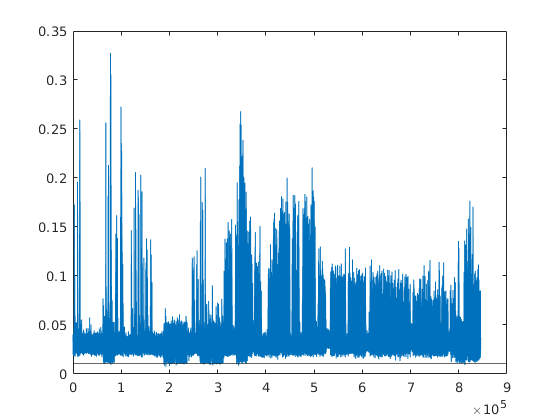

thr = 0.0650

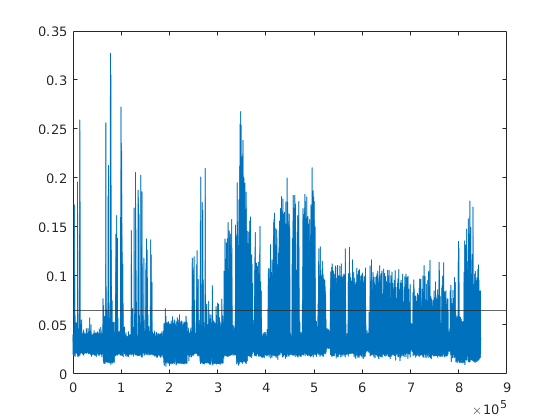

thr = 0.0650

times =         2455        2759        3563        9317       13103       13620       14033       14587       62245       63429       67529       68865       69350       72273       72734       73451       74194       77050       77774       78374       78859       79582       81020       81230       88228       88732       89139       89645       90332       90948       91504       92162       98514       98946       99373       99825      100271      100846      101379      102079      102937      103838      120904      121367      123557      126598      129469      130160      130686      131542



% find events sample time
times_prediction = times

times = sampleVector(times);

experiment.predictedSound.y = y

times_prediction =         2455        2759        3563        9317       13103       13620       14033       14587       62245       63429       67529       68865       69350       72273       72734       73451       74194       77050       77774       78374       78859       79582       81020       81230       88228       88732       89139       89645       90332       90948       91504       92162       98514       98946       99373       99825      100271      100846      101379      102079      102937      103838      120904      121367      123557      126598      129469      130160      130686      131542


experiment.predictedSound.sampleVector = sampleVector
experiment.predictedSound.events.all = times_prediction

% Add the events top the experiment object

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


experiment.sound_events.all = times

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


artifactStart = experiment.Conditions.artifact_times(2) * 30

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


artifactEnd = experiment.Conditions.artifact_times(1) * 30
all_times = [experiment.Conditions.all_changes + artifactStart,[experiment.Conditions.all_changes(2:end);sampleVector(end)]-artifactEnd]


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


`Divide the events to the experiment condition`

% Aluminum times
aluminumTimes = all_times(experiment.Conditions.condition_classification == 1,:)

artifactStart = 75000

aluminumEvents = []

artifactEnd = 90000

experiment.predictedSound.events.aluminum = [];

all_times = 33×2 int64 matrix
    4786818    6511339
    6676339    8400861
    8565861   10290384
   10455384   12173912
   12338912   14051438
   14216438   15928965
   16093965   17818491
   17983491   19696063
   19861063   21573592
   21738592   23463119


for al = 1:length(aluminumTimes)
    tempEvents = times(find(times > aluminumTimes(al,1) & times < aluminumTimes(al,2)))
    tempPredict = times_prediction(find(times > aluminumTimes(al,1) & times < aluminumTimes(al,2)))'
    aluminumEvents = [aluminumEvents;tempEvents]
    experiment.predictedSound.events.aluminum = [experiment.predictedSound.events.aluminum;tempPredict]
end

aluminumTimes = 8×2 int64 matrix
    4786818    6511339
   14216438   15928965
   16093965   17818491
   19861063   21573592
   21738592   23463119
   25505648   27224177
   59676650   61389170
   61554170   63278688


% non times


aluminumEvents =

     []



nonTimes = all_times(experiment.Conditions.condition_classification == 3,:)
experiment.predictedSound.events.non = [];
nonEvents = []
for non = 1:length(nonTimes)
    tempInd = times(find(times > nonTimes(non,1) & times < nonTimes(non,2)))
    tempPredict = times_prediction(find(times > nonTimes(non,1) & times < nonTimes(non,2)))'
    nonEvents = [nonEvents;tempInd]

tempEvents =      4837187
     5144878
     5245143
     5281539
     5500894
     5535496
     5589297
     5645058
     5859392
     5913734


tempPredict =        63429
       67529
       68865
       69350
       72273
       72734
       73451
       74194
       77050
       77774


aluminumEvents =      4837187
     5144878
     5245143
     5281539
     5500894
     5535496
     5589297
     5645058
     5859392
     5913734


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents = 14456890

tempPredict = 191604

aluminumEvents =      4837187
     5144878
     5245143
     5281539
     5500894
     5535496
     5589297
     5645058
     5859392
     5913734


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]



tempEvents =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector



aluminumEvents =      4837187
     5144878
     5245143
     5281539
     5500894
     5535496
     5589297
     5645058
     5859392
     5913734


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     19879932
    19951836
    19991235
    20196337
    20234985
    20267780
    20304026
    20350778
    20627470
    20698241


tempPredict =       263861
      264819
      265344
      268077
      268592
      269029
      269512
      270135
      273822
      274765


aluminumEvents =      4837187
     5144878
     5245143
     5281539
     5500894
     5535496
     5589297
     5645058
     5859392
     5913734


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     21778077
    22358708
    22582567
    22728309
    23233811


tempPredict =       289149
      296886
      299869
      301810
      308546


aluminumEvents =      4837187
     5144878
     5245143
     5281539
     5500894
     5535496
     5589297
     5645058
     5859392
     5913734


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     25506351
    25529917
    25625226
    25719037
    25762934
    25880604
    25910700
    25993549
    26047059
    26083011


tempPredict =       338828
      339142
      340412
      341662
      342247
      343815
      344216
      345320
      346033
      346512


aluminumEvents =      4837187
     5144878
     5245143
     5281539
     5500894
     5535496
     5589297
     5645058
     5859392
     5913734


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     60016788
    60068868
    60096334
    60124258
    60942484
    61054076
    61092200
    61166797
    61192831
    61254223


tempPredict =       798633
      799327
      799693
      800065
      810964
      812451
      812959
      813953
      814300
      815118


aluminumEvents =      4837187
     5144878
     5245143
     5281539
     5500894
     5535496
     5589297
     5645058
     5859392
     5913734


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     61561779
    61611889
    61652044
    61677032
    61696850
    61784045
    61826675
    62003935
    62095933
    62132783


tempPredict =       819216
      819884
      820419
      820752
      821016
      822178
      822746
      825107
      826333
      826824


aluminumEvents =      4837187
     5144878
     5245143
     5281539
     5500894
     5535496
     5589297
     5645058
     5859392
     5913734


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


    experiment.predictedSound.events.non = [experiment.predictedSound.events.non;tempPredict];
end

% muted times

nonTimes = 15×2 int64 matrix
    6676339    8400861
    8565861   10290384
   10455384   12173912
   17983491   19696063
   23628119   25340648
   31162226   32880750
   36818834   38543350
   38708350   40426870
   44364905   46083425
   48137941   49856504


mutedTimes = all_times(experiment.Conditions.condition_classification == 2,:)
experiment.predictedSound.events.muted = [];


nonEvents =

     []



mutedEvents = []
for mut = 1:length(mutedTimes)
    tempInd = times(find(times > mutedTimes(mut,1) & times < mutedTimes(mut,2)))
    tempPredict = times_prediction(find(times > mutedTimes(mut,1) & times < mutedTimes(mut,2)))'
    mutedEvents = [mutedEvents;tempInd]
    experiment.predictedSound.events.muted = [experiment.predictedSound.events.muted;tempPredict];

tempInd =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


tempPredict =        88228
       88732
       89139
       89645
       90332
       90948
       91504
       92162
       98514
       98946


nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


tempInd =      9151058
     9185799
     9350152
     9578374
     9793822
     9845683
     9885153
     9949395
    10191264
    10241698


tempPredict =       120904
      121367
      123557
      126598
      129469
      130160
      130686
      131542
      134765
      135437


nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


tempInd =     10599140
    10647174
    10683793
    10797788
    10854751
    11097895
    11388476
    11445513
    11513276
    11584799


tempPredict =       140200
      140840
      141328
      142847
      143606
      146846
      150718
      151478
      152381
      153334


nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


tempInd =     18619758
    18640772
    18691356
    18797093
    18855853
    18921521
    18978856
    19278889
    19299075
    19317013


tempPredict =       247069
      247349
      248023
      249432
      250215
      251090
      251854
      255852
      256121
      256360


nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


tempInd =     23648369
    23735273
    23776619
    23817825
    23867505
    23909606
    23951106
    23988026
    24024497
    24051962


tempPredict =       314070
      315228
      315779
      316328
      316990
      317551
      318104
      318596
      319082
      319448


nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


tempInd =     31202043
    31232661
    31261037
    31290225
    31321516
    31349583
    31403548
    31430411
    31461336
    31487967


tempPredict =       414712
      415119
      415497
      415886
      416302
      416676
      417395
      417753
      418165
      418520


nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


tempInd =     36857594
    36891365
    36911553
    36944348
    36968965
    36996207
    37016092
    37053237
    37107737
    37139174


tempPredict =       490065
      490515
      490784
      491221
      491549
      491912
      492177
      492672
      493398
      493817


nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


tempInd =     38720757
    38747246
    38769985
    38809610
    38830172
    38889612
    38907096
    38945826
    39003229
    39045853


tempPredict =       514891
      515244
      515547
      516075
      516349
      517141
      517374
      517890
      518655
      519223


nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


tempInd =     44392589
    44417728
    44446924
    44469514
    44504483
    44530524
    44571423
    44592215
    44614428
    44636861


tempPredict =       590466
      590801
      591190
      591491
      591953
      592300
      592845
      593122
      593418
      593717


nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


tempInd =     48159518
    48182554
    48204471
    48242144
    48264730
    48299777
    48333024
    48351258
    48367847
    48389007


tempPredict =       640651
      640958
      641250
      641752
      642053
      642520
      642963
      643206
      643427
      643709


nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


tempInd =     51924355
    51956170
    52024693
    52061100
    52090583
    52127656
    52147395
    52185593
    52216361
    52242184


tempPredict =       690816
      691240
      692153
      692638
      693031
      693525
      693788
      694297
      694707
      695051


nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


tempInd =     53802758
    53823620
    53841710
    53859415
    53885829
    53909017
    53931305
    53951869
    53972806
    53999679


tempPredict =       715836
      716114
      716355
      716590
      716942
      717251
      717548
      717822
      718101
      718459


nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


tempInd =     55706071
    55726477
    55752295
    55770987
    55794547
    55815637
    55851429
    55903060
    55918972
    55965800


tempPredict =       741192
      741464
      741808
      742057
      742371
      742652
      743129
      743817
      744029
      744653


nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


tempInd =     57602103
    57749273
    57792420
    57819060
    57846900
    57870092
    57890208
    57910017
    57931555
    57967806


tempPredict =       766457
      768418
      768993
      769348
      769719
      770028
      770296
      770560
      770847
      771330


nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047



tempInd =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector



nonEvents =      6698570
     6736385
     6766930
     6804901
     6856456
     6902685
     6944406
     6993788
     7470631
     7503047


end

timeWind = 1;

mutedTimes = 10×2 int64 matrix
   12338912   14051438
   27389177   29107704
   29272704   30997226
   33045750   34764315
   34929315   36653834
   40591870   42310389
   42475389   44199905
   46248425   47972941
   50021504   51746020
   59463094   59511650


numBins = 20;

rasters_aluminum = {}


mutedEvents =

     []



psth_aluminum = []
for un = 1:length(experiment.Units.good.id)
    rasters_aluminum{un} = createRaster(aluminumEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted aluminum events unit id',num2str(un)])
    psth_aluminum(un,:) = psth(rasters_aluminum{un},numBins);
end

tempInd = 12367903

tempPredict = 163769

mutedEvents = 12367903

tempInd =     27400442
    27417550
    27477063
    27524943
    27574547
    27607869
    27663481
    27705049
    27753083
    27805911


tempPredict =       364067
      364295
      365088
      365726
      366387
      366831
      367572
      368126
      368766
      369470


mutedEvents =     12367903
    27400442
    27417550
    27477063
    27524943
    27574547
    27607869
    27663481
    27705049
    27753083


tempInd =     29275317
    29385415
    30433054
    30466292
    30518002
    30564758
    30620438
    30679503
    30718230
    30744866


tempPredict =       389046
      390513
      404467
      404910
      405599
      406222
      406964
      407751
      408267
      408622


mutedEvents =     12367903
    27400442
    27417550
    27477063
    27524943
    27574547
    27607869
    27663481
    27705049
    27753083


tempInd =     33074217
    33127872
    33154896
    33183483
    33259355
    33286224
    33324120
    33398489
    33424381
    33475716


tempPredict =       439657
      440372
      440732
      441113
      442124
      442482
      442987
      443978
      444323
      445007


mutedEvents =     12367903
    27400442
    27417550
    27477063
    27524943
    27574547
    27607869
    27663481
    27705049
    27753083


tempInd =     34970559
    35006885
    35039380
    35079006
    35110444
    35148047
    35184593
    35214309
    35244857
    35281406


tempPredict =       464925
      465409
      465842
      466370
      466789
      467290
      467777
      468173
      468580
      469067


mutedEvents =     12367903
    27400442
    27417550
    27477063
    27524943
    27574547
    27607869
    27663481
    27705049
    27753083


tempInd =     40595026
    40629175
    40659193
    40703992
    40743469
    40767482
    40802454
    40826993
    40849657
    40900616


tempPredict =       539865
      540320
      540720
      541317
      541843
      542163
      542629
      542956
      543258
      543937


mutedEvents =     12367903
    27400442
    27417550
    27477063
    27524943
    27574547
    27607869
    27663481
    27705049
    27753083


tempInd =     42507504
    42880709
    42909154
    42932420
    42948784
    43000863
    43046335
    43061950
    43097004
    43134592


tempPredict =       565349
      570322
      570701
      571011
      571229
      571923
      572529
      572737
      573204
      573705


mutedEvents =     12367903
    27400442
    27417550
    27477063
    27524943
    27574547
    27607869
    27663481
    27705049
    27753083


tempInd =     46301377
    46344608
    46376124
    46402390
    46430536
    46456873
    46481345
    46507529
    46534547
    46560591


tempPredict =       615894
      616470
      616890
      617240
      617615
      617966
      618291
      618640
      619000
      619347


mutedEvents =     12367903
    27400442
    27417550
    27477063
    27524943
    27574547
    27607869
    27663481
    27705049
    27753083


tempInd =     50040245
    50060960
    50082203
    50102238
    50129398
    50155297
    50176453
    50203852
    50249624
    50307112


tempPredict =       665711
      665987
      666270
      666537
      666899
      667244
      667526
      667891
      668501
      669267


mutedEvents =     12367903
    27400442
    27417550
    27477063
    27524943
    27574547
    27607869
    27663481
    27705049
    27753083


tempInd = 59486211

tempPredict = 791563

mutedEvents =     12367903
    27400442
    27417550
    27477063
    27524943
    27574547
    27607869
    27663481
    27705049
    27753083


rasters_muted = {}
psth_muted = []
for un = 1:length(experiment.Units.good.id)
    rasters_muted{un} = createRaster(mutedEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_muted(un,:) = psth(rasters_muted{un},numBins);


rasters_aluminum =

  0×0 empty cell array



end


psth_aluminum =

     []



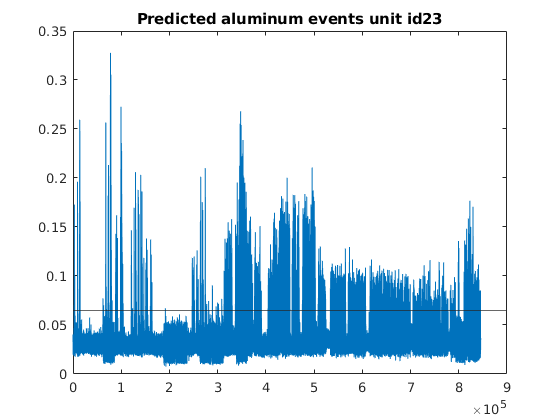

rasters_non = {}
psth_non = []
for un = 1:length(experiment.Units.good.id)
    rasters_non{un} = createRaster(nonEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])

    psth_non(un,:) = psth(rasters_non{un},numBins);
end


rasters_muted =

  0×0 empty cell array




psth_muted =

     []



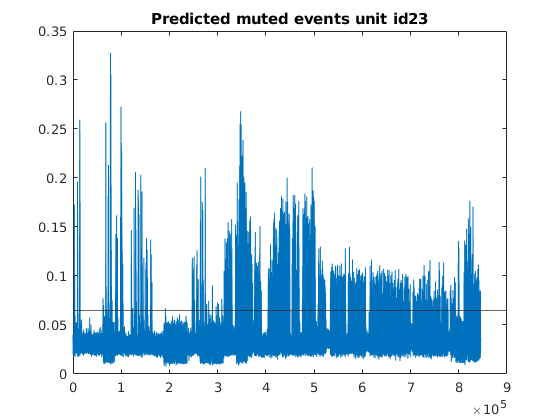

rasters_aluminumMua = {}
psth_aluminumMua = []
for un = 1:length(experiment.Units.mua.id)
    rasters_aluminumMua{un} = createRaster(aluminumEvents,experiment.Units.mua.times(un,:),timeWind);
    title(['Predicted aluminum events unit id',num2str(un)])

    psth_aluminumMua(un,:) = psth(rasters_aluminumMua{un},numBins);
end


rasters_non =

  0×0 empty cell array



rasters_mutedMua = {}


psth_non =

     []



psth_mutedMua = []
for un = 1:length(experiment.Units.mua.id)
    rasters_mutedMua{un} = createRaster(mutedEvents,experiment.Units.mua.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_mutedMua(un,:) = psth(rasters_mutedMua{un},numBins);

end

rasters_nonMua = {}
psth_nonMua = []
for un = 1:length(experiment.Units.mua.id)


rasters_aluminumMua =

  0×0 empty cell array



    rasters_nonMua{un} = createRaster(nonEvents,experiment.Units.mua.times(un,:),timeWind);


psth_aluminumMua =

     []



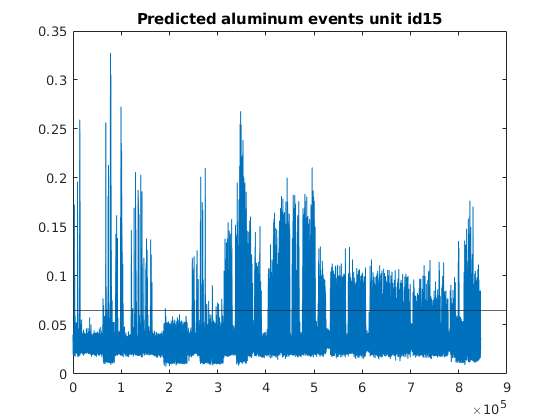

    title(['Predicted muted events unit id',num2str(un)])
    psth_nonMua(un,:) = psth(rasters_nonMua{un},numBins);
end

psth_aluminumAll = [psth_aluminum;psth_aluminumMua]


rasters_mutedMua =

  0×0 empty cell array



psth_mutedAll = [psth_muted;psth_mutedMua]


psth_mutedMua =

     []



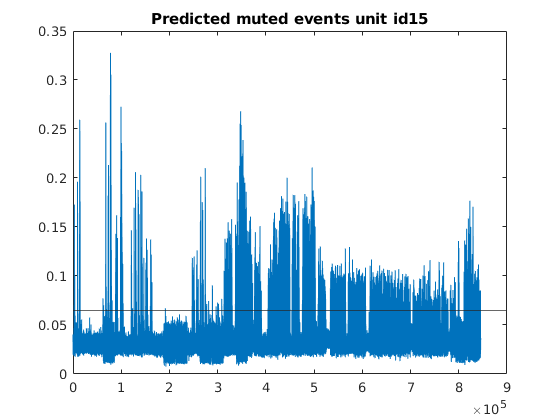

psth_nonAll = [psth_non;psth_nonMua]

aud_units = find(experiment.evokedEvents.pVal(:,2) == 1);


rasters_nonMua =

  0×0 empty cell array



[~,time_vector] = psth(rasters_non{1},numBins);


psth_nonMua =

     []



mutSTD = std(psth_mutedAll(aud_units,:))/sqrt(length(aud_units))
alumSTD = std(psth_aluminumAll(aud_units,:))/sqrt(length(aud_units))
nonSTD = std(psth_nonAll(aud_units,:))/sqrt(length(aud_units))

figure; 

psth_aluminumAll =     0.0952    0.0159    0.0397    0.1111    0.0556    0.0476    0.0635    0.0635    0.0397    0.0476    0.0556    0.0952    0.0238    0.0476    0.0635    0.0714    0.0397    0.0714    0.0952    0.0714    0.0714    0.0635    0.0794    0.0397    0.0317    0.0476    0.0873    0.0476    0.0714    0.0794    0.0556    0.0635    0.0635    0.0317    0.0556    0.1111    0.0714    0.0476    0.0397    0.0714    0.0952    0.0952    0.0476    0.0714    0.0794    0.0794    0.1111    0.0397    0.0873    0.0476
    0.0635    0.0635    0.0556    0.0476    0.0714    0.0952    0.1032    0.0873    0.0714    0.1032    0.0556    0.0476    0.0556    0.0873    0.1032    0.0476    0.0873    0.0397    0.0556    0.0873    0.0635    0.1032    0.0635    0.0873    0.0873    0.0873    0.1032    0.0794    0.0556    0.0714    0.0556    0.0556    0.0635    0.0556    0.0635    0.1111    0.1190    0.0794    0.0714    0.1190    0.1032    0.0794    0.1111    0.0873    0.1190    0.0794    0.0476    0.0714

hold on


psth_mutedAll =     0.0599    0.1168    0.0988    0.0689    0.0778    0.0808    0.0629    0.0689    0.0629    0.0868    0.0659    0.0838    0.0778    0.0629    0.0719    0.0868    0.0808    0.0808    0.0749    0.0808    0.0868    0.1048    0.0808    0.0778    0.0898    0.0838    0.1048    0.0988    0.0659    0.0988    0.0749    0.0659    0.0629    0.0898    0.0689    0.0808    0.1018    0.0808    0.0808    0.1018    0.0749    0.1018    0.0629    0.0539    0.0868    0.0898    0.1048    0.0808    0.0719    0.0778
    0.0749    0.0749    0.0449    0.0659    0.0659    0.0838    0.0778    0.0659    0.0569    0.0569    0.0689    0.0659    0.0689    0.0599    0.0749    0.0629    0.0808    0.0719    0.0539    0.0569    0.0419    0.0509    0.0479    0.0449    0.0389    0.0509    0.0689    0.0539    0.0299    0.0659    0.0778    0.0659    0.0659    0.0958    0.0808    0.0569    0.0479    0.0689    0.0689    0.0778    0.0659    0.0928    0.0838    0.0689    0.0689    0.0838    0.0509    0.0509   

plot(time_vector,mean(psth_aluminumAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.Aluminum)

psth_nonAll =     0.0760    0.0780    0.0955    0.0877    0.0858    0.0897    0.0799    0.1033    0.0780    0.0721    0.0955    0.0702    0.0702    0.0877    0.0780    0.0760    0.1072    0.0975    0.0936    0.0897    0.0838    0.1053    0.0663    0.0682    0.0916    0.0819    0.0838    0.0877    0.1014    0.1092    0.0643    0.0643    0.0897    0.0741    0.0799    0.0955    0.0916    0.0760    0.0780    0.0858    0.0819    0.1053    0.0565    0.0682    0.0975    0.0780    0.0936    0.0760    0.0955    0.1111
    0.0507    0.0526    0.0507    0.0487    0.0604    0.0643    0.0585    0.0624    0.0682    0.0663    0.0624    0.0799    0.0487    0.0702    0.0975    0.0799    0.0624    0.0702    0.0487    0.0526    0.0663    0.0507    0.0468    0.0429    0.0546    0.0565    0.0546    0.0624    0.0682    0.0585    0.0448    0.0546    0.0390    0.0565    0.0370    0.0624    0.0526    0.0409    0.0409    0.0429    0.0390    0.0409    0.0702    0.0819    0.0682    0.0565    0.0370    0.0546    0

errorbar(time_vector,mean(psth_aluminumAll(aud_units,:)),alumSTD,'LineWidth',0.1,'Color',experiment.color.Aluminum)
hold on
plot(time_vector,mean(psth_mutedAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.Muted)
errorbar(time_vector,mean(psth_mutedAll(aud_units,:)),mutSTD,'LineWidth',0.1,'Color',experiment.color.Muted)
plot(time_vector,mean(psth_nonAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.noObject)

mutSTD =     0.0066    0.0080    0.0087    0.0079    0.0079    0.0071    0.0079    0.0077    0.0070    0.0078    0.0091    0.0070    0.0075    0.0069    0.0071    0.0083    0.0083    0.0086    0.0082    0.0076    0.0081    0.0082    0.0102    0.0087    0.0076    0.0078    0.0096    0.0081    0.0086    0.0082    0.0077    0.0097    0.0090    0.0078    0.0095    0.0067    0.0089    0.0090    0.0074    0.0093    0.0075    0.0089    0.0085    0.0073    0.0086    0.0084    0.0083    0.0080    0.0074    0.0077


errorbar(time_vector,mean(psth_nonAll(aud_units,:)),nonSTD,'LineWidth',0.1,'Color',experiment.color.noObject)

alumSTD =     0.0083    0.0077    0.0074    0.0090    0.0079    0.0087    0.0077    0.0084    0.0085    0.0088    0.0086    0.0102    0.0056    0.0063    0.0080    0.0091    0.0082    0.0095    0.0100    0.0089    0.0085    0.0097    0.0091    0.0102    0.0075    0.0103    0.0113    0.0082    0.0085    0.0073    0.0062    0.0069    0.0079    0.0089    0.0100    0.0082    0.0085    0.0133    0.0091    0.0091    0.0076    0.0072    0.0091    0.0098    0.0094    0.0079    0.0081    0.0059    0.0069    0.0083


meanSound.aluminumMean = meanMatrix(experiment.predictedSound.events.aluminum,1,400)

nonSTD =     0.0071    0.0067    0.0076    0.0062    0.0063    0.0066    0.0072    0.0068    0.0066    0.0064    0.0071    0.0074    0.0070    0.0077    0.0064    0.0079    0.0073    0.0076    0.0064    0.0069    0.0063    0.0065    0.0070    0.0061    0.0063    0.0065    0.0064    0.0070    0.0069    0.0071    0.0064    0.0067    0.0068    0.0066    0.0073    0.0073    0.0062    0.0061    0.0067    0.0060    0.0070    0.0069    0.0067    0.0064    0.0075    0.0064    0.0067    0.0071    0.0071    0.0075


figure; plot(mean(y(meanSound.aluminumMean)))
hold on
meanSound.mutedMean = meanMatrix(experiment.predictedSound.events.muted,1,400)
plot(mean(y(meanSound.mutedMean)))
meanSound.nonMean = meanMatrix(experiment.predictedSound.events.non,1,400)
plot(mean(y(meanSound.nonMean)))

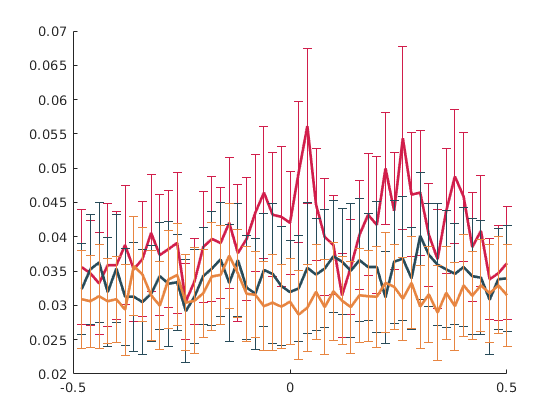

meanSound.aluminumMean = meanMatrix(aluminumEvents,1,30000);
figure; plot(mean(experiment.sound_events.fullSound(meanSound.aluminumMean)));
hold on;
meanSound.mutedMean = meanMatrix(mutedEvents,1,30000);
plot(mean(experiment.sound_events.fullSound(meanSound.mutedMean)));

meanSound.nonMean = meanMatrix(nonEvents,1,30000)
plot(mean(experiment.sound_events.fullSound(meanSound.nonMean)));

meanSound = struct with fields:
    aluminumMean: [126×400 double]


experiment.sound_events.aluminum = aluminumTimes;
experiment.sound_events.muted = mutedTimes;
experiment.sound_events.non = nonTimes;

meanSound = struct with fields:
    aluminumMean: [126×400 double]
       mutedMean: [334×400 double]


experiment.PSTHs.alum = psth_aluminumAll;
experiment.PSTHs.muted = psth_mutedAll;

meanSound = struct with fields:
    aluminumMean: [126×400 double]
       mutedMean: [334×400 double]
         nonMean: [513×400 double]


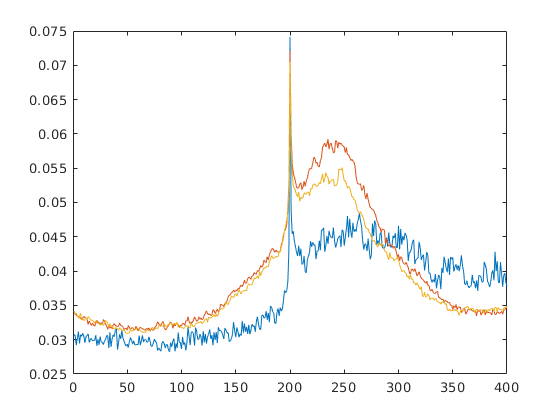

experiment.PSTHs.non = psth_nonAll;

%experiment.PSTHs.audUnits = aud_units;
experiment.PSTHs.time_vector = time_vector;

experiment.sound_events.aluminumEvents = aluminumEvents;
experiment.sound_events.mutedEvents = mutedEvents;
experiment.sound_events.nonEvents = nonEvents;

%params = '/home/ben/Z/Parameters_files/FVB/FVB103_270721_849.m';
run(params)

meanSound = struct with fields:
    aluminumMean: [126×30000 double]
       mutedMean: [334×30000 double]
         nonMean: [513×30000 double]


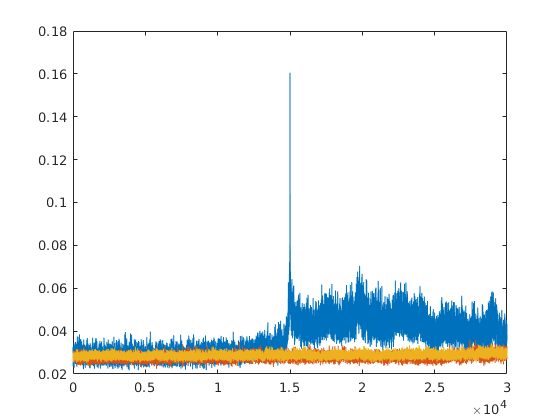

save([expName,'.mat'],'experiment')